img_name = "test1.jpg"

img_name = "test1.jpg"

choice = 2

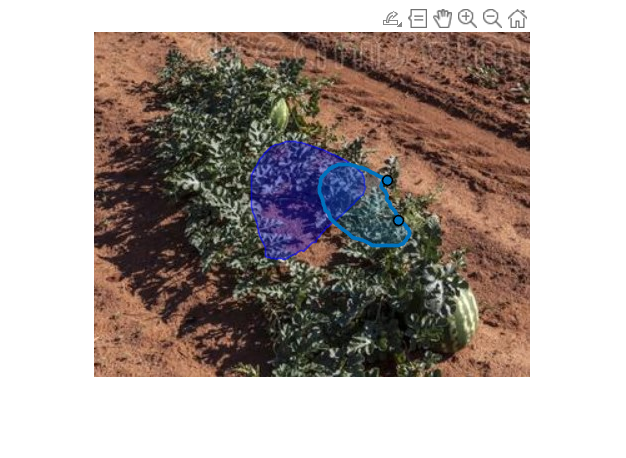

choice = 0

img = double(imread(img_name))./255;

mask = lasso_select(img, nan);
close

while true
    choice = get_input()
    
    if choice == 0
        break
    end
    
%     disp_img = 0.4.*img + ...
%         0.6.*double(repmat((ones(size(mask))-mask), ...
%         [1, 1, 3])).*img;
    
    curr_mask = lasso_select(img, mask);
    
    if choice == 1          %add
        mask = max(mask, curr_mask);
    elseif choice == 2      %remove
        mask = mask-mask.*curr_mask;
    end
    
end



% display
imshow(img)
coord = mask2poly(mask, 'CW');
hold on 
ps = polyshape(uint16(coord(:,1)), uint16(coord(:,2)));

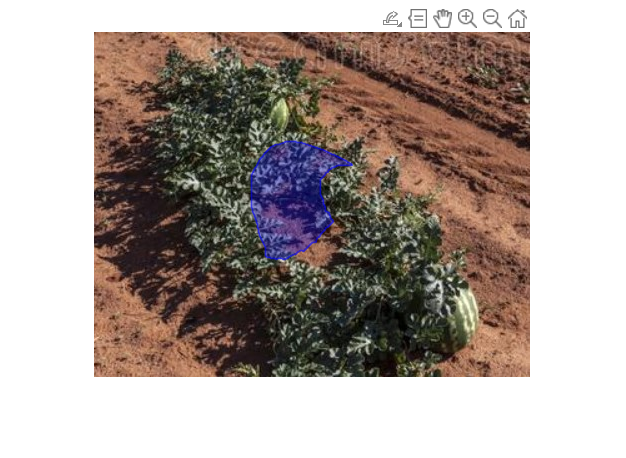

plot(ps, 'FaceAlpha', 0.3, 'FaceColor', 'b', ...
         'EdgeAlpha', 0.6, 'EdgeColor', 'b', 'LineWidth', 1);
hold off 

imwrite( logical(mask), strcat(img_name, '_mask.tiff'));